## load sample data

load('/home/hiroyuki/TT/sample.mat');

## PCA decomposition

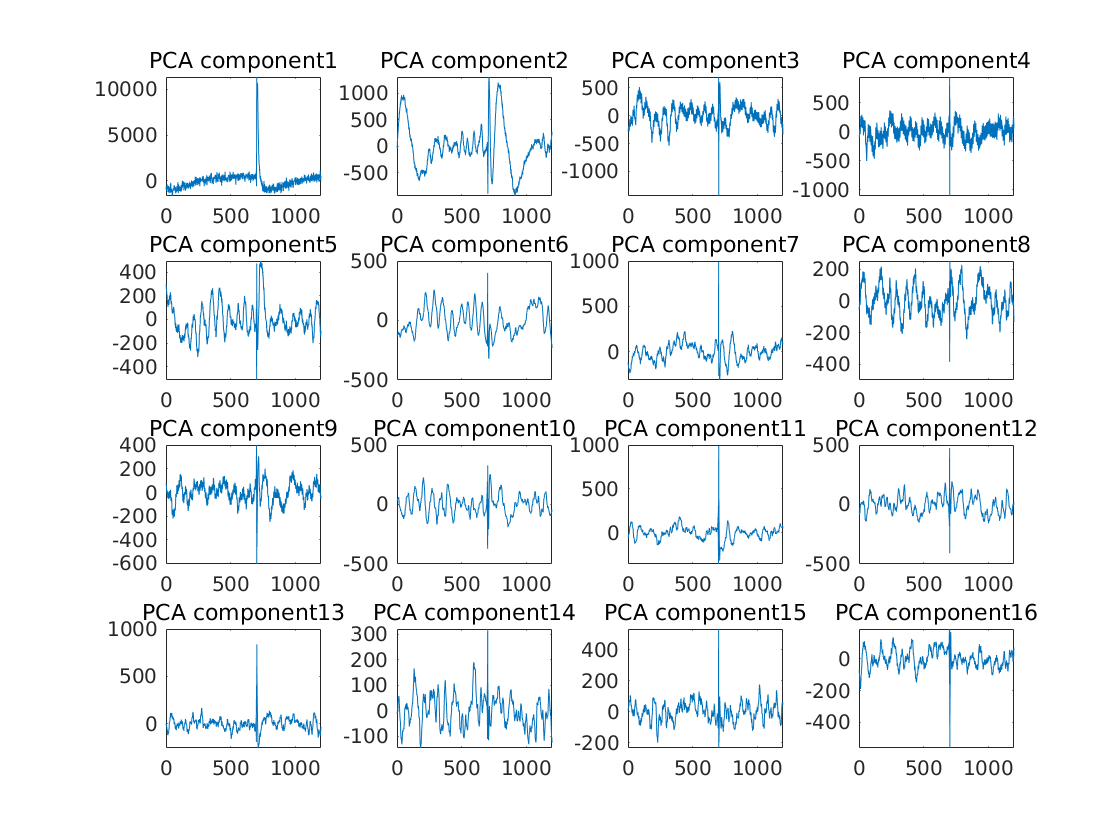

[recon, score,eivalue,eivector] = PCAanal_v2(data, 1, data);

close all;figure(1); 
for n=1:16 
    subplot(4,4,n); plot(score(:,n));
    subtitle(['PCA component' num2str(n)])
end 

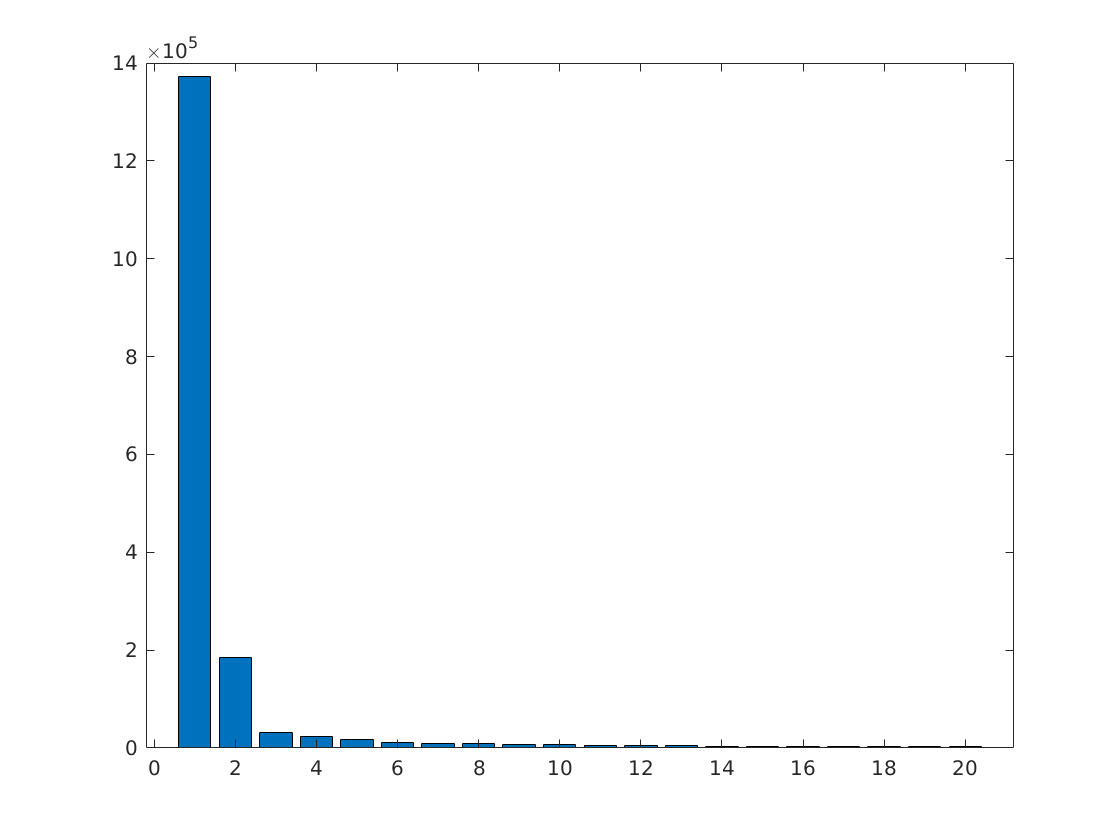

figure(3) ;bar(eivalue(1:20))

## PCA denoising and reconstruction

% Discard PC 1 3 and 4 
[recon, score,eivalue,eivector] = PCAanal_v2(data, [1 3 4], data);

## See the results

figure(2); clf; ch = [1:10:100]

ch =      1    11    21    31    41    51    61    71    81    91


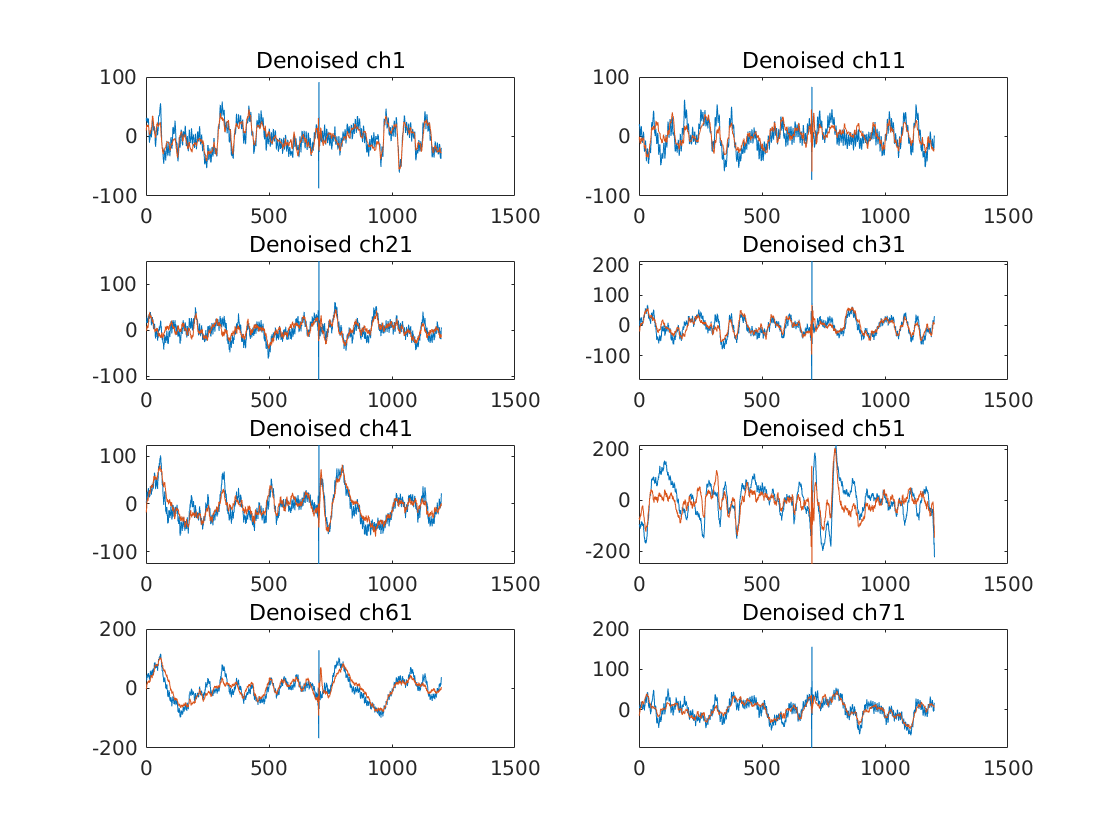

for n=1:8 
    m = ch(n);
    subplot(4,2,n); plot(data(:,m));hold on; plot(recon(:,m));
    subtitle(['Denoised ch' num2str(m)])
end